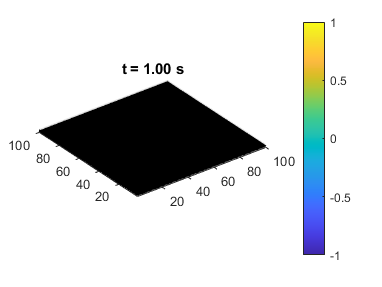

% Set the sound velocity and the time step
c = 1500; % m/s
dt = 0.01; % s

% Set the size of the grid
xmax = 100; % m
ymax = 100; % m
zmax = 100; % m

% Set the grid resolution
dx = 1; % m
dy = 1; % m
dz = 1; % m

% Set the initial pressure distribution
P0 = zeros(xmax/dx,ymax/dy,zmax/dz);
P0(50,50,50) = 1;

% Set the simulation time
tmax = 1; % s

% Initialize the pressure field
P = P0;

% Create a figure window
figure;

% Loop over the simulation time
for t = 0:dt:tmax
  % Loop over the grid points
  for i = 2:xmax/dx-1
    for j = 2:ymax/dy-1
      for k = 2:zmax/dz-1
        % Compute the second-order derivatives of the pressure
        d2Pdx2 = (P(i+1,j,k) - 2*P(i,j,k) + P(i-1,j,k))/dx^2;
        d2Pdy2 = (P(i,j+1,k) - 2*P(i,j,k) + P(i,j-1,k))/dy^2;
        d2Pdz2 = (P(i,j,k+1) - 2*P(i,j,k) + P(i,j,k-1))/dz^2;
        % Update the pressure field using the wave equation
        P(i,j,k) = P(i,j,k) + c^2*dt^2*(d2Pdx2 + d2Pdy2 + d2Pdz2);
      end
    end
  end
  
  % Plot the current pressure field
  slice(P,[],[],50)
  axis equal;
  caxis([-1 1]);
  colorbar;
  title(sprintf('t = %.2f s',t));
  drawnow;
end